# Total Drag Calculation

## Parameters

%CL_cruise=0.3707;
M=0.7;
AR_w=8.5;
%Sweep_angle=0.5236;
AR_t=3;
MAC=23.5511 ;%ft
%q=255.2868; %lb/ft2
d=7.38*10^-4   %lbs/ft3 air density at 35000ft

d = 7.3800e-04

V_cruise=677.6

V_cruise = 677.6000

q=0.5*d*V_cruise*V_cruise

q = 169.4233

%mu=2.995e-7
Wing_Area=3.7793e+3 %ft2

Wing_Area = 3.7793e+03

e_w=0.8

e_w = 0.8000

%CL_t=0.058685
e_t=4.61*(1-0.045*AR_t^0.68)*(cos(35*pi/180))^(0.15)-3.1

e_t = 0.9491

s_h=801.2417

s_h = 801.2417

## Friction drag

AOA_w=-10:0.1:15

AOA_w =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


AOA_t=AOA_w+0.8251

AOA_t =    -9.1749   -9.0749   -8.9749   -8.8749   -8.7749   -8.6749   -8.5749   -8.4749   -8.3749   -8.2749   -8.1749   -8.0749   -7.9749   -7.8749   -7.7749   -7.6749   -7.5749   -7.4749   -7.3749   -7.2749   -7.1749   -7.0749   -6.9749   -6.8749   -6.7749   -6.6749   -6.5749   -6.4749   -6.3749   -6.2749   -6.1749   -6.0749   -5.9749   -5.8749   -5.7749   -5.6749   -5.5749   -5.4749   -5.3749   -5.2749   -5.1749   -5.0749   -4.9749   -4.8749   -4.7749   -4.6749   -4.5749   -4.4749   -4.3749   -4.2749



S_wet_w=(3.7793e+3)*2

S_wet_w = 7.5586e+03

S_ref_w=Wing_Area

S_ref_w = 3.7793e+03

S_wet_t=801.2417*2

S_wet_t = 1.6025e+03

S_ref_t=(s_h)

S_ref_t = 801.2417

MAC_t=17.3432

MAC_t = 17.3432

Re_w=V_cruise*MAC/0.00040573   %Reynolds number

Re_w = 3.9332e+07

Re_t=V_cruise*MAC_t/0.00040573

Re_t = 2.8964e+07


C_f_w=0.455/(((log10(Re_w))^(2.58))*(1+0.144*M^2)^(0.65)) %turbulance

C_f_w = 0.0023


C_f_t=0.455/(((log10(Re_t))^(2.58))*(1+0.144*M^2)^(0.65)) %turbulance

C_f_t = 0.0024

## Zero lift drag

CDo_w=(C_f_w*S_wet_w./S_ref_w)*1.25

CDo_w = 0.0058

CD0_w=CDo_w+CDo_w*0.05

CD0_w = 0.0061


CDo_t=(C_f_t*S_wet_t./S_ref_t)*1.25

CDo_t = 0.0061

CD0_t=CDo_t+CDo_t*0.05

CD0_t = 0.0064

## Induced drag

CL_alpha=5.3099

CL_alpha = 5.3099

zeroL_AOA=(-3)

zeroL_AOA = -3


CL_w=(CL_alpha*pi/180).*(AOA_w-zeroL_AOA)

CL_w =    -0.6487   -0.6395   -0.6302   -0.6209   -0.6117   -0.6024   -0.5931   -0.5839   -0.5746   -0.5653   -0.5561   -0.5468   -0.5375   -0.5282   -0.5190   -0.5097   -0.5004   -0.4912   -0.4819   -0.4726   -0.4634   -0.4541   -0.4448   -0.4356   -0.4263   -0.4170   -0.4078   -0.3985   -0.3892   -0.3800   -0.3707   -0.3614   -0.3522   -0.3429   -0.3336   -0.3244   -0.3151   -0.3058   -0.2966   -0.2873   -0.2780   -0.2688   -0.2595   -0.2502   -0.2410   -0.2317   -0.2224   -0.2132   -0.2039   -0.1946


CDi_w=(CL_w.^2)./(pi*e_w*AR_w)

CDi_w =     0.0197    0.0191    0.0186    0.0180    0.0175    0.0170    0.0165    0.0160    0.0155    0.0150    0.0145    0.0140    0.0135    0.0131    0.0126    0.0122    0.0117    0.0113    0.0109    0.0105    0.0101    0.0097    0.0093    0.0089    0.0085    0.0081    0.0078    0.0074    0.0071    0.0068    0.0064    0.0061    0.0058    0.0055    0.0052    0.0049    0.0046    0.0044    0.0041    0.0039    0.0036    0.0034    0.0032    0.0029    0.0027    0.0025    0.0023    0.0021    0.0019    0.0018



beta=(1-M^2)^(1/2)

beta = 0.7141

Sweep_h=35*pi/180

Sweep_h = 0.6109

dCl_to_dalpha=2*pi

dCl_to_dalpha = 6.2832

CL_alpha_t=(2*pi*AR_t)/(2+(4+(AR_t^2*beta^2*(1+(tan(Sweep_h)/beta)^2))/(dCl_to_dalpha/(2*pi))^2)^0.5)

CL_alpha_t = 3.3624


CL_t=(CL_alpha_t*pi/180).*(AOA_t)

CL_t =    -0.5384   -0.5326   -0.5267   -0.5208   -0.5150   -0.5091   -0.5032   -0.4974   -0.4915   -0.4856   -0.4797   -0.4739   -0.4680   -0.4621   -0.4563   -0.4504   -0.4445   -0.4387   -0.4328   -0.4269   -0.4211   -0.4152   -0.4093   -0.4035   -0.3976   -0.3917   -0.3859   -0.3800   -0.3741   -0.3682   -0.3624   -0.3565   -0.3506   -0.3448   -0.3389   -0.3330   -0.3272   -0.3213   -0.3154   -0.3096   -0.3037   -0.2978   -0.2920   -0.2861   -0.2802   -0.2743   -0.2685   -0.2626   -0.2567   -0.2509


CDi_t=(CL_t.^2)./(pi*e_t*AR_t)

CDi_t =     0.0324    0.0317    0.0310    0.0303    0.0296    0.0290    0.0283    0.0277    0.0270    0.0264    0.0257    0.0251    0.0245    0.0239    0.0233    0.0227    0.0221    0.0215    0.0209    0.0204    0.0198    0.0193    0.0187    0.0182    0.0177    0.0172    0.0166    0.0161    0.0156    0.0152    0.0147    0.0142    0.0137    0.0133    0.0128    0.0124    0.0120    0.0115    0.0111    0.0107    0.0103    0.0099    0.0095    0.0091    0.0088    0.0084    0.0081    0.0077    0.0074    0.0070


## Total drag

D=q*(((CD0_w+CDi_w).*Wing_Area)+((CD0_t+CDi_t).*s_h))

D =    1.0e+04 *

    2.1795    2.1342    2.0895    2.0454    2.0020    1.9591    1.9169    1.8753    1.8343    1.7939    1.7542    1.7151    1.6766    1.6387    1.6014    1.5647    1.5287    1.4933    1.4585    1.4243    1.3908    1.3579    1.3255    1.2939    1.2628    1.2323    1.2025    1.1733    1.1447    1.1167    1.0893    1.0626    1.0365    1.0110    0.9861    0.9618    0.9382    0.9152    0.8928    0.8710    0.8498    0.8293    0.8093    0.7900    0.7714    0.7533    0.7358    0.7190    0.7028    0.6872


CD=D./(q*(Wing_Area+s_h))

CD =     0.0281    0.0275    0.0269    0.0264    0.0258    0.0252    0.0247    0.0242    0.0236    0.0231    0.0226    0.0221    0.0216    0.0211    0.0206    0.0202    0.0197    0.0192    0.0188    0.0184    0.0179    0.0175    0.0171    0.0167    0.0163    0.0159    0.0155    0.0151    0.0147    0.0144    0.0140    0.0137    0.0134    0.0130    0.0127    0.0124    0.0121    0.0118    0.0115    0.0112    0.0110    0.0107    0.0104    0.0102    0.0099    0.0097    0.0095    0.0093    0.0091    0.0089


L=q*((CL_w.*Wing_Area)+(CL_t.*s_h))

L =    1.0e+05 *

   -4.8847   -4.8174   -4.7501   -4.6828   -4.6155   -4.5482   -4.4809   -4.4136   -4.3463   -4.2790   -4.2117   -4.1444   -4.0770   -4.0097   -3.9424   -3.8751   -3.8078   -3.7405   -3.6732   -3.6059   -3.5386   -3.4713   -3.4040   -3.3367   -3.2694   -3.2021   -3.1348   -3.0674   -3.0001   -2.9328   -2.8655   -2.7982   -2.7309   -2.6636   -2.5963   -2.5290   -2.4617   -2.3944   -2.3271   -2.2598   -2.1925   -2.1252   -2.0578   -1.9905   -1.9232   -1.8559   -1.7886   -1.7213   -1.6540   -1.5867


L2D=L./D

L2D =   -22.4120  -22.5725  -22.7333  -22.8942  -23.0550  -23.2156  -23.3759  -23.5356  -23.6945  -23.8525  -24.0092  -24.1645  -24.3181  -24.4696  -24.6188  -24.7652  -24.9086  -25.0486  -25.1846  -25.3162  -25.4430  -25.5644  -25.6799  -25.7887  -25.8903  -25.9840  -26.0690  -26.1445  -26.2096  -26.2636  -26.3053  -26.3338  -26.3481  -26.3469  -26.3291  -26.2935  -26.2386  -26.1633  -26.0659  -25.9451  -25.7992  -25.6267  -25.4260  -25.1954  -24.9333  -24.6378  -24.3073  -23.9401  -23.5346  -23.0891


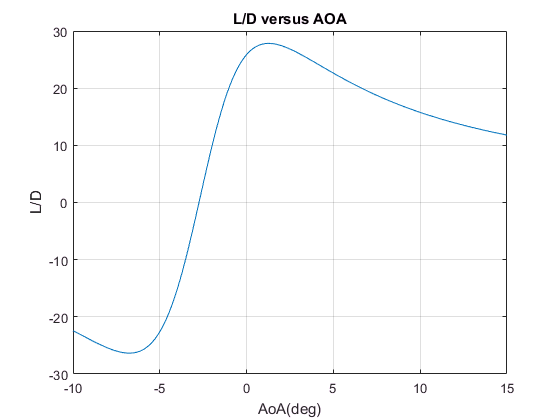

plot(AOA_w,L2D)
title('L/D versus AOA')
xlabel('AoA(deg)')
ylabel('L/D')

xlim([-10.0 15.0])
ylim([-30.0 30.0])
grid on

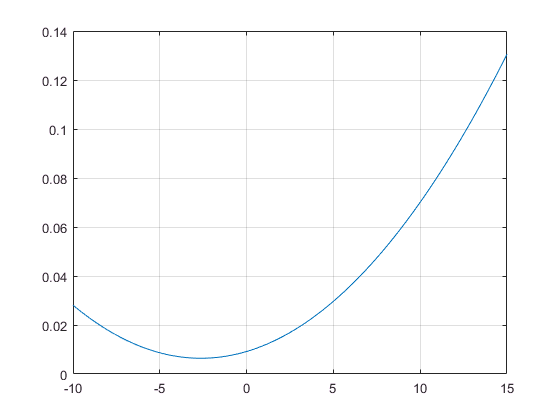


plot(AOA_w,CD)
grid on